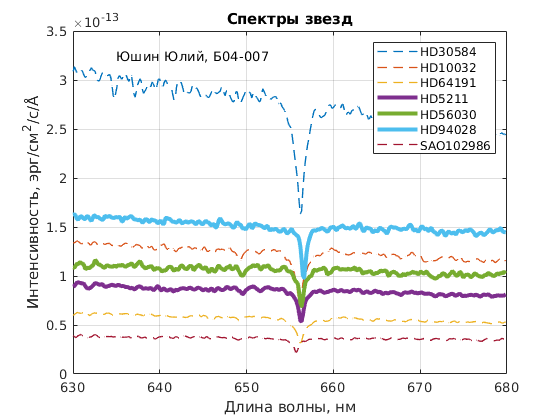

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

lambdaNorm = 656.28;
lightSpeed = 299792.458;
nObs = size(spectra, 1);
nStars = size(spectra,2);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

[sHa, idx] = min(spectra);
lambdaHa = lambda(idx)';
z = (lambdaHa / lambdaNorm) - 1;
speed = z * lightSpeed;

fg1 = figure;
for i = 1:1:nStars
    if z(i) > 0
        plot(lambda, spectra(:, i), 'LineWidth',3)
        hold on
    else
        plot(lambda, spectra(:, i), '--', 'LineWidth',1)
        hold on
    end
end
set(fg1, 'Visible', 'on');
xlabel('Длина волны, нм');
ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
title('Спектры звезд');
legend(starNames);
text(635, 3.25*10^(-13), 'Юшин Юлий, Б04-007')
grid on;
saveas(fg1, 'spectra.png');


movaway = starNames(z>0);